# COL·LECCIÓ EXERCICIS

## CONCEPTES BÀSICS

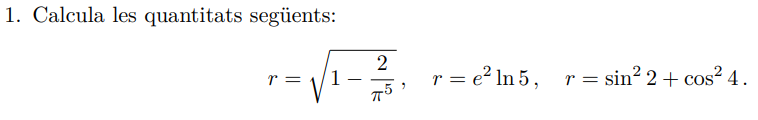

r = sqrt(1-(2/pi^5)), r1 = exp(2)*log(5), r2 = sin(2)^2 + cos(4)^2

r =          0.996726879698693

r1 =           11.8922270227214

r2 =            1.2540717935275

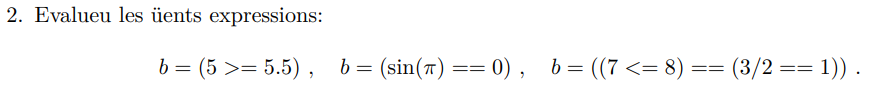

b = (5 >= 5.5), b1 = sin(pi) == 0, b2 = ((7 <= 8) == (3/2 == 1))

b = logical
   0

b1 = logical
   0

b2 = logical
   0

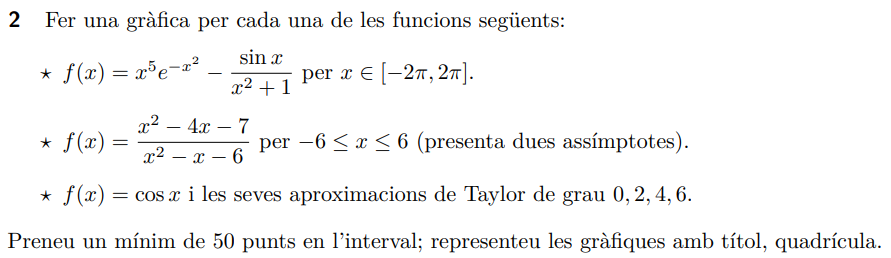

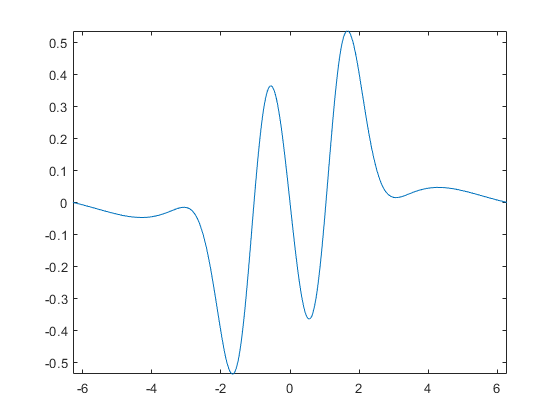

f = @(x) x.^5.*exp(-x.^2) - (sin(x)./(x.^2+1));
fplot(f, [-2*pi, 2*pi])

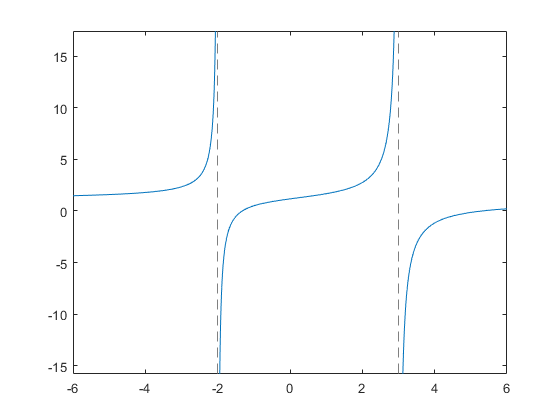

f = @(x) (x.^2 -4.*x-7)./(x.^2-x-6);
fplot(f,[-6,6])

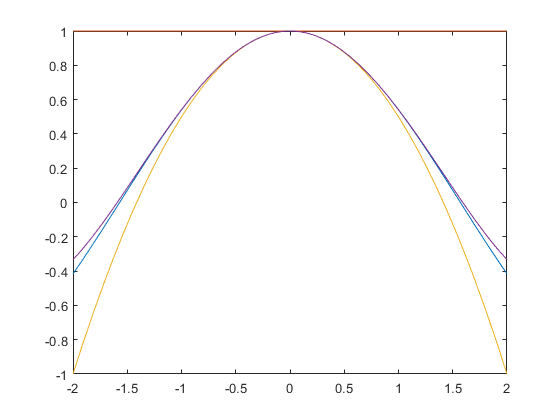

syms t
fs(t) = cos(t);
p2(t) = taylor(fs(t),t,0,'Order',2);
p4(t) = taylor(fs(t),t,0,'Order',4);
p6(t) = taylor(fs(t),t,0,'Order',6);
fplot([fs,p2,p4,p6],[-2,2])

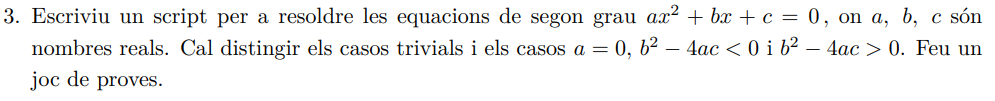

x = roots([2,-12,6])', xa = my_roots([2,-12,6])

x =           5.44948974278318         0.550510257216822


xa =           5.44948974278318         0.550510257216822


ea = abs(x - xa)

ea =       8.88178419700125e-16      3.33066907387547e-16


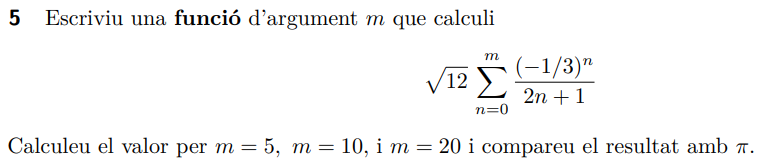

format longG
S5 = sumapi(5); S10 = sumapi(10); S20 = sumapi(20);
R = [S5,S10,S20]; r = abs(R-pi); R = [R;r]';
T = array2table(R,...
    'VariableNames',{'S','|S-pi|'},"RowNames",{'m=5','m=10','m=20'}); disp(T)

                   S                   |S-pi|       
            ________________    ____________________
    m=5     3.14130878546288    0.000283868126909947
    m=10    3.14159330450308     6.5091328815825e-07
    m=20    3.14159265359564    5.84199355557757e-12


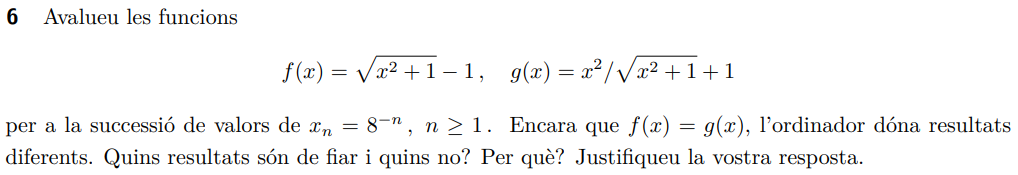

format shortG
f = @(x) sqrt(x.^2 + 1) - 1;
g = @(x) x.^2./(sqrt(x.^2 + 1) + 1);
n = 1:15;
x = 8.^(-n);
R = [n; x; f(x); g(x)]';
T = array2table(R,...
    "VariableNames",{'n','8^(-n)','f(8^-n)','g(8^-n)'}); disp(T)

    n       8^(-n)       f(8^-n)       g(8^-n)  
    __    __________    __________    __________
     1         0.125     0.0077822     0.0077822
     2      0.015625    0.00012206    0.00012206
     3     0.0019531    1.9073e-06    1.9073e-06
     4    0.00024414    2.9802e-08    2.9802e-08
     5    3.0518e-05    4.6566e-10    4.6566e-10
     6    3.8147e-06     7.276e-12     7.276e-12
     7    4.7684e-07    1.1369e-13    1.1369e-13
     8    5.9605e-08    1.7764e-15    1.7764e-15
     9    7.4506e-09             0    2.7756e-17
    10    9.3132e-10             0    4.3368e-19
    11    1.1642e-10             0    6.7763e-21
    12    1.4552e-11             0    1.0588e-22
    13     1.819e-12             0    1.6544e-24
    14    2.2737e-13             0    2.5849e-26
    15    2.8422e-14             0     4.039e-28


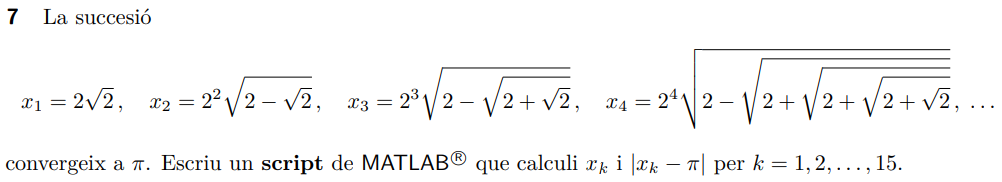

x(1) = 2*sqrt(2); y = sqrt(2);
for k = 2:15
    x(k) = 2^k * sqrt(2-y);
    y = sqrt(2+y);
end
ea = abs(x - pi);
R = [1:15; x; ea]';
T = array2table(R,...
    "VariableNames",{'k','x_k','|x_k - pi|'}); disp(T)

    k      x_k      |x_k - pi|
    __    ______    __________
     1    2.8284       0.31317
     2    3.0615      0.080125
     3    3.1214      0.020148
     4    3.1365     0.0050442
     5    3.1403     0.0012615
     6    3.1413     0.0003154
     7    3.1415    7.8852e-05
     8    3.1416    1.9713e-05
     9    3.1416    4.9283e-06
    10    3.1416    1.2321e-06
    11    3.1416    3.0798e-07
    12    3.1416    7.7045e-08
    13    3.1416    2.0127e-08
    14    3.1416    1.2178e-09
    15    3.1416    8.2686e-09


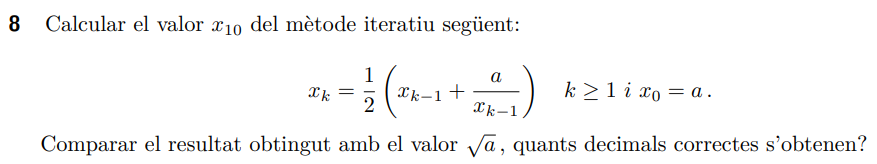

clearvars;
alpha = 2;
x(1) = alpha;
for k = 2:10
    x(k) = 1/2*(x(k-1) + alpha/x(k-1));
end
ea = abs(x - sqrt(alpha));
er = ea/sqrt(alpha);
R = [x; ea; er]';
T = array2table(R,...
    'VariableNames',{'x_k','ea_k','er_k'})

T = 10×3 table
     x_k         ea_k          er_k   
    ______    __________    __________
         2       0.58579       0.41421
       1.5      0.085786       0.06066
    1.4167     0.0024531     0.0017346
    1.4142    2.1239e-06    1.5018e-06
    1.4142    1.5947e-12    1.1276e-12
    1.4142    2.2204e-16    1.5701e-16
    1.4142    2.2204e-16    1.5701e-16
    1.4142    2.2204e-16    1.5701e-16
    1.4142    2.2204e-16    1.5701e-16
    1.4142    2.2204e-16    1.5701e-16

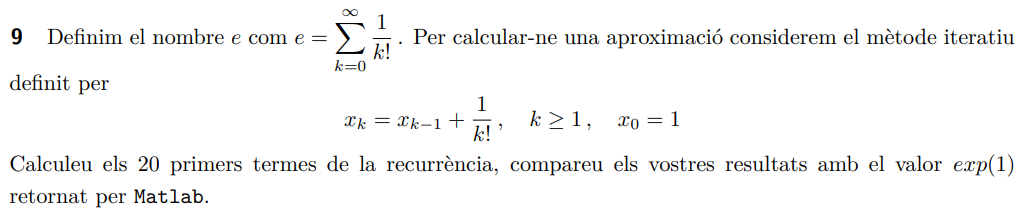

clearvars;
x(1) = 1 + 1; fact(1) = 1; ve = exp(1);
for k = 2:20
    fact(k) = k*fact(k-1);
    x(k) = x(k-1) + 1/fact(k);
end
ea = abs(x - exp(1));
R = [x; ea]';
T = array2table(R,...
    'VariableNames',{'x_k','ea_k'}); disp(T)

     x_k         ea_k   
    ______    __________
         2       0.71828
       2.5       0.21828
    2.6667      0.051615
    2.7083     0.0099485
    2.7167     0.0016152
    2.7181    0.00022627
    2.7183     2.786e-05
    2.7183    3.0586e-06
    2.7183    3.0289e-07
    2.7183    2.7313e-08
    2.7183    2.2606e-09
    2.7183    1.7288e-10
    2.7183    1.2286e-11
    2.7183    8.1535e-13
    2.7183    5.0626e-14
    2.7183    2.6645e-15
    2.7183             0
    2.7183             0
    2.7183             0
    2.7183             0


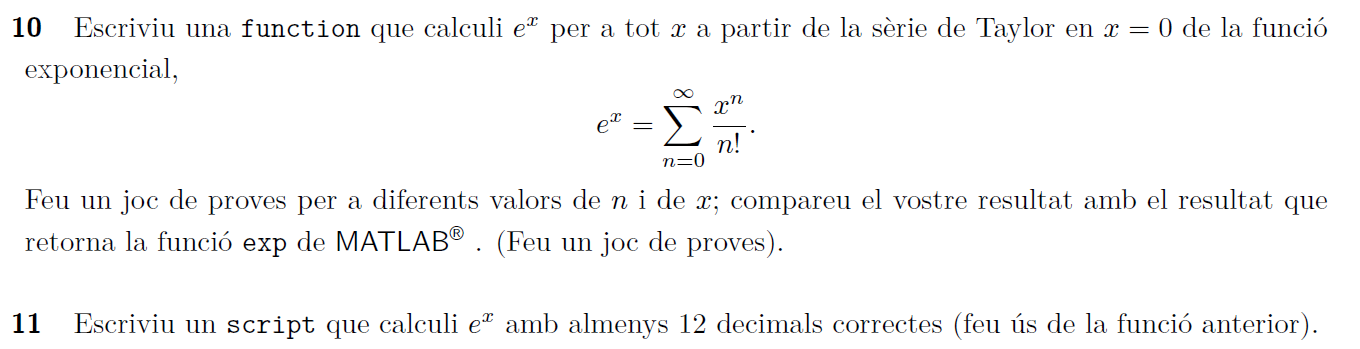

format longG
x = 14.1; n = 40;
my_exp(x,n); my_exp(-x,n);

El falor de e^(14.1) calculat de Matlab és 1329083.28081209282391
El valor de e^(14.1) aproximat és 1329083.27494041924365; es tenen 1 decimals correctes i 8 xifres significatives

El falor de e^(-14.1) calculat de Matlab és 0.00000075239830
El valor de e^(-14.1) aproximat és 0.00000075239851; es tenen 12 decimals correctes i 6 xifres significatives



x = 1.87; n = 20;
my_exp(x,n); my_exp(-x,n);

El falor de e^(1.87) calculat de Matlab és 6.48829639928671
El valor de e^(1.87) aproximat és 6.48829639928659; es tenen 12 decimals correctes i 13 xifres significatives

El falor de e^(-1.87) calculat de Matlab és 0.15412366181513
El valor de e^(-1.87) aproximat és 0.15412366181545; es tenen 12 decimals correctes i 11 xifres significatives



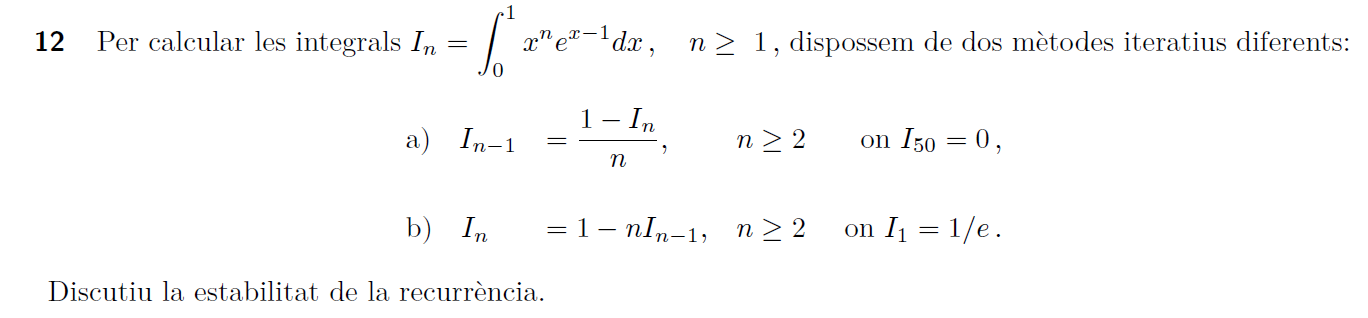

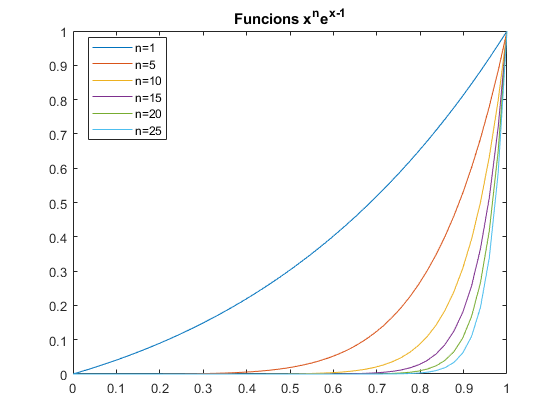

% a) correcte b) incorrecte
g = @(x,n) x.^n.*exp(x-1);
x = linspace(0,1,50);
plot(x,g(x,1)), hold on
for n = 1:5
    plot(x,g(x,n*5))
end
hold off
title('Funcions x^ne^{x-1}'),legend('n=1','n=5','n=10','n=15','n=20','n=25','Location','best')

- apartat a)

format shortG
J(50) = 0;
for n = 50:-1:2
    J(n-1) = (1-J(n))/n;
end

- apartat b)

I(1) = exp(-1);
for n = 2:50
    I(n) = 1-n*I(n-1);
end

- valor aproximat per integració numèrica

for n = 1:50
    ve(n) = integral(@(x)x.^n.*exp(x-1),0,1);
end

- taula comparativa de resultats

n = 1:50;
R = [n; ve; J; I]';
T = array2table(R,...
    'VariableNames',{'n','ve','apartat a)','apartat b)'}); disp(T)

    n        ve       apartat a)    apartat b) 
    __    ________    __________    ___________
     1     0.36788      0.36788         0.36788
     2     0.26424      0.26424         0.26424
     3     0.20728      0.20728         0.20728
     4     0.17089      0.17089         0.17089
     5     0.14553      0.14553         0.14553
     6      0.1268       0.1268          0.1268
     7     0.11238      0.11238         0.11238
     8     0.10093      0.10093         0.10093
     9    0.091612     0.091612        0.091612
    10    0.083877     0.083877        0.083877
    11    0.077352     0.077352        0.077352
    12    0.071773     0.071773        0.071773
    13    0.066948     0.066948        0.066948
    14    0.062732     0.062732        0.062731
    15    0.059018     0.059018        0.059034
    16    0.055719     0.055719        0.055459


- taula comparativa d'errors

Re = [n;abs(ve-J); abs(ve-I)]';
Te = array2table(Re,...
    'VariableNames',{'n','apartat a)','apartat b)'}); disp(Te)

    n     apartat a)    apartat b)
    __    __________    __________
     1    5.5511e-17    5.5511e-17
     2    5.5511e-17    5.5511e-17
     3    5.5511e-17    1.1102e-16
     4             0    2.7756e-16
     5    2.7756e-17    1.4988e-15
     6             0    8.9373e-15
     7    1.3878e-17    6.2658e-14
     8             0    5.0113e-13
     9    1.3878e-17    4.5102e-12
    10    1.3878e-17    4.5101e-11
    11    1.3878e-17    4.9612e-10
    12    1.3878e-17    5.9534e-09
    13    1.3878e-17    7.7394e-08
    14             0    1.0835e-06
    15    6.9389e-18    1.6253e-05
    16    6.9389e-18    0.00026004
    17    1.3878e-17     0.0044208
    18    6.9389e-18      0.079574
    19    6.9389e-18        1.5119
    20    1.3878e-17        30.238
    21             0           635
    22    6.9389e-18         13970
    23    6.9389e-18    3.2131e+05
    24             0   

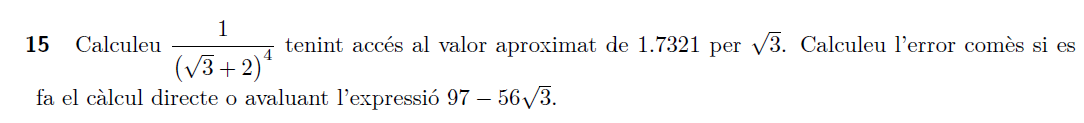

Cálcul del valor

x = sqrt(3); xa = 1.7321; f = 1/(x+2)^4; fa = 1/(xa+2)^4; 
g = 97-56*x; ga = 97-56*xa;

Anàlisi de l'error

ea = abs(x-xa), eaf = abs(f-fa)

ea =    4.9192e-05

eaf =    2.7177e-07

eag = abs(g-ga)    % Al fer 56*^sqrt(3) fa que amplifiqui l'error

eag =     0.0027548